# PWM and Serial Comms

Open the data port from MATLAB. 

clear s % closes ports already open
s = serialport('COM4',9600) % Check COM#

s =   Serialport with properties:

                 Port: "COM4"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


Write a message to send the duty cycle.

s.writeline("0.5"); % write duty cycle to Pico

In MATLAB, plot the data points of Hole # vs. Duty Cycle. The notional line or curve nearest to these points represents the load characteristic.

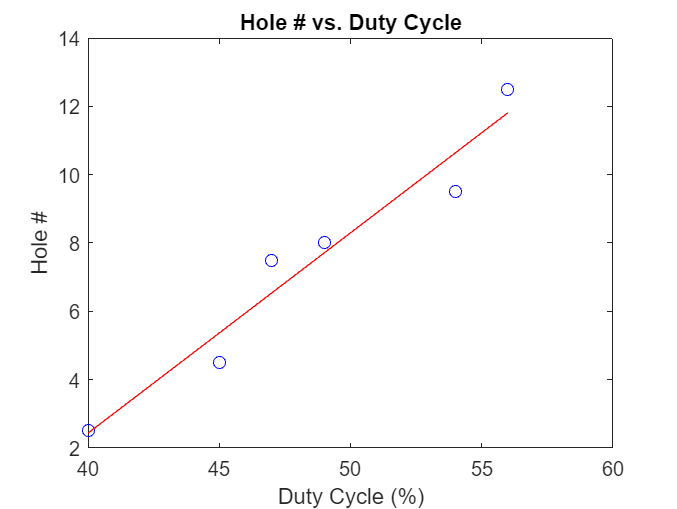

duty_cycle = [40 45 47 49 54 56]; % expiremented duty cycles
hole_num = [2.5 4.5 7.5 8 9.5 12.5]; % resultant hold number
plot(duty_cycle, hole_num,'bo') % plot points

pfit = polyfit(duty_cycle,hole_num,1); % fit line to data 
pval = polyval(pfit,duty_cycle); % evaulate fitted line
hold on
plot(duty_cycle,pval, 'r') % plot fitted line
hold off

title("Hole # vs. Duty Cycle")
xlabel("Duty Cycle (%)")
ylabel("Hole #")